% The simulated of different conditions are run parallelly on the cluster
% using batch processing of MATLAB.
% The way batch processing works: there are two steps
% 1. call the cluster that you want to use by 'parcluster'. 'parcluster()'
% will call the default cluster of what you set up for MATLAB. In my case
% it's the MATLAB local cluster.
% 2. use batch('script') to submit the script to run parallely


SimulationName='Simulation_Multiplexing_50ns_20240503';

savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_Multiplexing/';
% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_Multiplexing/Simulation_Multiplexing_50ns_20240503/'

cd(filepath)

% Define the double exponential decay parameters and other parameters in
% the simulation

% SS_samples_A = 200000:5000:1200000;
SS_samples_A = 100000:5000:1200000;
SS_samples_B = [100000 500000 1000000];

tau1=2; % tau1 
tau2_all=[2.5 3 3.5 4 6]; % tau2 

afterpulse_ratio=0.0032; % Afterpulse ratio experimentally determined as 0.32% of the fluorescence signal

% make a folder to save the simulated data
mkdir('Simulated_data')

% load the atuofluorescence fitting results and the delta peak time to
% adjust the prf

load("AKAR_baseline_fitting_parameters.mat")
load('Autofluo_fitting_parameters')
dpt = mean(dpt_all(1:10)) % Use the mean of delta peak time from 10 fitting from baseline of the experimental data

dpt = -0.0860

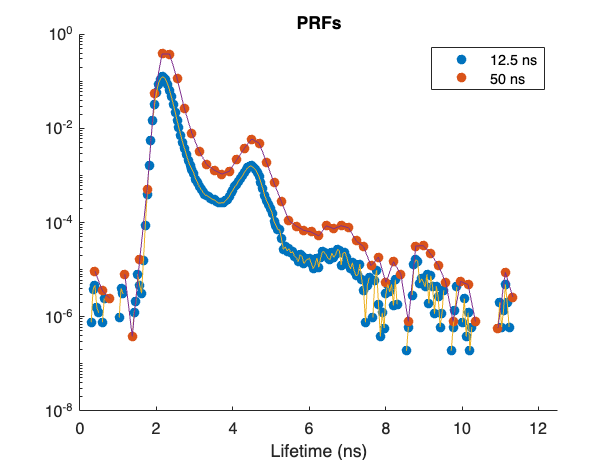


% Adjust IRF by dpt
PrfName_original = 'prf_InsightBottomGreen_20231017.mat'; % This is the original collected IRF file
load(PrfName_original) % Load the original prf file
x = (1:1:256)*(12.5/256); % Spreading the x axis (256 time channels) over 12.5ns
prf_interp1=interp1(x,prf,x+dpt,'linear'); % Adjust the prf based on delta peak time
prf_interp1(isnan(prf_interp1)) = 0; % Make the nan values to 0 after interpolation
prf_original = prf_interp1; % IRF variable has to be saved under the name prf

x_axis = 1:1:256;
prf_50ns = zeros(1,256);

for i = 1:64
    prf_50ns(i) = sum(prf_original((i-1)*4+1:(i-1)*4+4));

end

figure
scatter(x_axis*(12.5/256), prf_original, 'filled')
hold on
scatter(x_axis*(50/256), prf_50ns, 'filled')
hold on
plot(x_axis*(12.5/256), prf_original)
hold on
plot(x_axis*(50/256), prf_50ns)
xlim([0 12.5])
xlabel('Lifetime (ns)')
set(gca,'yscale', 'log')
legend('12.5 ns', '50 ns')
title('PRFs')


prf = prf_50ns;

% save the new prf as new file
PrfName = 'Prf_interp1_50ns.mat' 

PrfName = 'Prf_interp1_50ns.mat'

save(PrfName, 'prf')

% Generation of population A
PopulationName='Simulation_population_A_2ns.mat'; % Define single exponential population name
GenPop512_exp1_v2(1000000, tau1, 50, PopulationName);  % Generate the single exponential population


PopulationName='Simulation_population_A_2ns_125.mat'; % Define single exponential population name
GenPop512_exp1_v2(1000000, tau1, 12.5, PopulationName);  % Generate the single exponential population

edit GenPop512_exp1_v2

x_axis = 0:1:511

x_axis =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


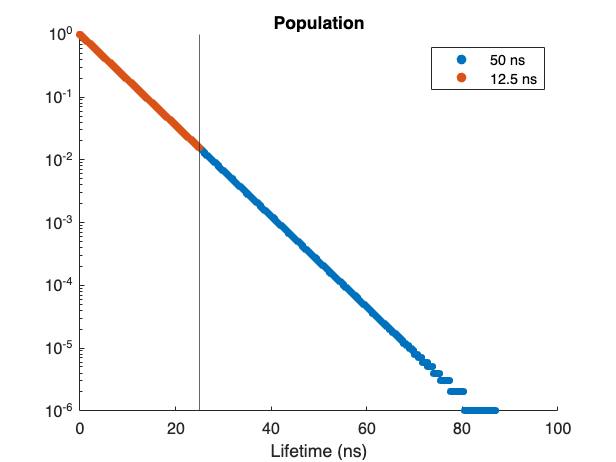


load('Simulation_population_B_6ns.mat')
Population_50ns = counts/max(counts);

load('Simulation_population_B_6ns_125.mat')
Population_125ns = counts/max(counts);

figure
scatter(x_axis*(50/256), Population_50ns, 20, 'filled')
hold on
scatter(x_axis*(12.5/256), Population_125ns, 20, 'filled')
% xlim([0 35])
xlabel('Lifetime (ns)')
xline([25])
set(gca,'yscale', 'log')
legend('50 ns', '12.5 ns')
title('Population')

Population_125ns = Population_125ns';


sum(Population_125ns(1:128)*(50/256))/sum(Population_125ns*(50/256))

ans = 0.6573

t = [0 12.5 50]

t =          0   12.5000   50.0000


y = zeros(1,3)

y =      0     0     0



for i_t = 1:3
    i = t(i_t);
    y(i_t) = -6*exp(-i/6)
end

y =     -6     0     0


y =    -6.0000   -0.7471         0


y =    -6.0000   -0.7471   -0.0014



a = y + 6

a =          0    5.2529    5.9986



a(2)/a(3)

ans = 0.8757

a(2)

ans = 5.2529

a(3)

ans = 5.9986

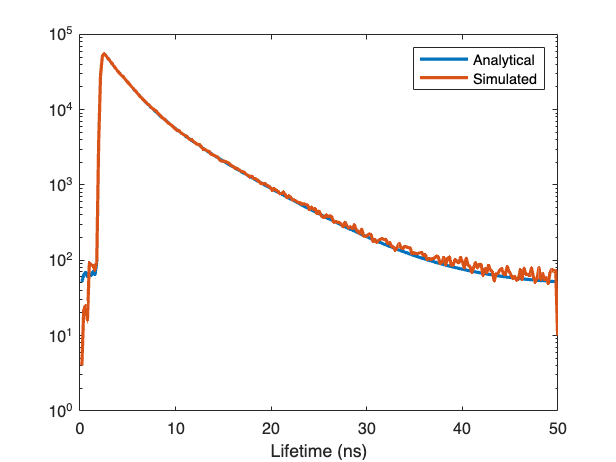

% Sanity check
load('Simulation_population_A_2ns.mat')
Population_50ns_A_conv = conv(counts, prf);
Population_50ns_A_conv = Population_50ns_A_conv(1:256) + Population_50ns_A_conv(257:512);
A_norm = Population_50ns_A_conv/sum(Population_50ns_A_conv);

load('Simulation_population_B_6ns.mat')
Population_50ns_B_conv = conv(counts, prf);
Population_50ns_B_conv = Population_50ns_B_conv(1:256) + Population_50ns_B_conv(257:512);
B_norm = Population_50ns_B_conv/sum(Population_50ns_B_conv);

histogram_analytical = A_norm*500000 + B_norm*500000 + autofluo_number*autofluo_50ns + bkgrd_sum/256;

load('Simulated_data/SampleA_500000_sensor.mat')
A_sim = n_sensor_all(1,:);

load('Simulated_data/SampleB_6_500000_sensor.mat')
B_sim = n_sensor_all(1,:);

load('Simulated_data/bkgrd_AP_1000000.mat')
load('Simulated_data/autoF_1000000.mat')

histogram_sim = A_sim + B_sim + n_bkgrd_all(1, :) + n_auto_all(1, :);

figure
semilogy((1:1:256)*(50/256), histogram_analytical, 'LineWidth', 2)
hold on
semilogy((1:1:256)*(50/256), histogram_sim, 'LineWidth', 2)
xlabel('Lifetime (ns)')
legend('Analytical', 'Simulated')

% Determining what's the approximate tau for autofluorescence 

tau_test = 1:0.1:2

tau_test =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


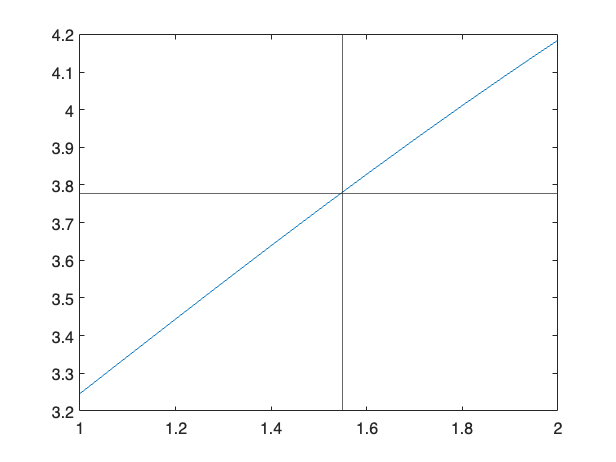

EmpLft_all = zeros(1, length(tau_test));
EmpLft_AF = CalcEmpLft([1 64], autofluo_50ns, 50);

xsim = (1:1:512)*(50/256);

for i = 1:length(tau_test)

    tau = tau_test(i);
    histogram_fitted = Exp1Hist(xsim, tau, 100000, prf);
    EmpLft_all(i) = CalcEmpLft([1 64], histogram_fitted, 50);

end

figure
plot(tau_test, EmpLft_all)
yline(EmpLft_AF)
xline(1.55)

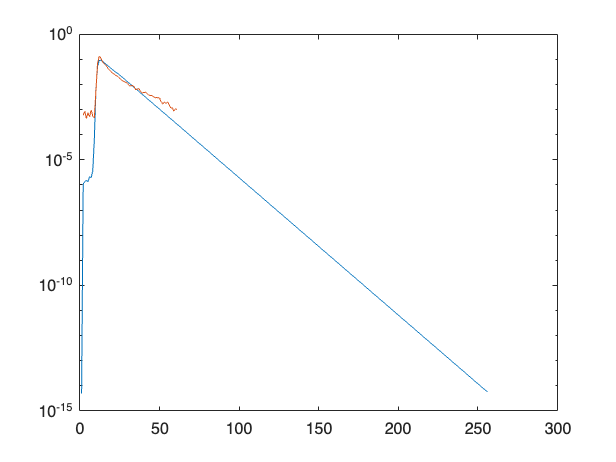


xsim = (1:1:512)*(50/256);
histogram_auto = Exp1Hist(xsim, 1.55, 100000, prf);
histogram_auto_norm = histogram_auto/sum(histogram_auto);

figure
semilogy(histogram_auto_norm)
hold on
semilogy(autofluo_50ns)

% Use the analytical histogram for fitting
% 1. generate the analytical histogram

tau2 = 2.5;
Sensor_A_photons = 100000;
Sensor_B_photons = 500000;


load('Simulation_population_A_2ns.mat')
Population_50ns_A_conv = conv(counts, prf);
Population_50ns_A_conv = Population_50ns_A_conv(1:256) + Population_50ns_A_conv(257:512);
A_norm = Population_50ns_A_conv/sum(Population_50ns_A_conv);

load(['Simulation_population_B_', num2str(tau2), 'ns.mat'])
Population_50ns_B_conv = conv(counts, prf);
Population_50ns_B_conv = Population_50ns_B_conv(1:256) + Population_50ns_B_conv(257:512);
B_norm = Population_50ns_B_conv/sum(Population_50ns_B_conv);

histogram_analytical = A_norm*Sensor_A_photons + B_norm*Sensor_B_photons + autofluo_number*autofluo_50ns;% + bkgrd_sum/256;

tau2 = 6;
Sensor_A_photons = 100000;
Sensor_B_photons = 500000;
tau_adding = 1.55;
histogram_adding = Exp1Hist(xsim, tau_adding, 1000000, prf);
histogram_adding = histogram_adding/sum(histogram_adding);

load('Simulation_population_A_2ns.mat')
Population_50ns_A_conv = conv(counts, prf);
Population_50ns_A_conv = Population_50ns_A_conv(1:256) + Population_50ns_A_conv(257:512);
A_norm = Population_50ns_A_conv/sum(Population_50ns_A_conv);

load(['Simulation_population_B_', num2str(tau2), 'ns.mat'])
Population_50ns_B_conv = conv(counts, prf);
Population_50ns_B_conv = Population_50ns_B_conv(1:256) + Population_50ns_B_conv(257:512);
B_norm = Population_50ns_B_conv/sum(Population_50ns_B_conv);

histogram_analytical = A_norm*Sensor_A_photons + B_norm*Sensor_B_photons + autofluo_number*histogram_adding;% + bkgrd_sum/256;

% 2. Use the analytical histogram for fitting

global FixBackground FixedBackground beta_iterations step_iterations sse_iterations

beta_iterations = {};
step_iterations = {};
sse_iterations = {};

FixBackground = 1;
FixedBackground = 0;

ch = 1; % only for FLIM channel 1
load(PrfName)
spc.fits{1}.prf = prf;
channel_width = 50/256;
pulse_width = 50;
range = [1 256];
spc.datainfo.psPerUnit = (50/256)*1000;
spc.datainfo.pulseInt = 50;
spc.fits{1}.fitstart = range(1)*spc.datainfo.psPerUnit/1000;
spc.fits{1}.fitend = range(2)*spc.datainfo.psPerUnit/1000;

chan = 1;

spc.fits{1}.beta2 = tau1; % fix the tau1
spc.fits{1}.beta4 = tau2; % Define the B lifetime and fix it for fitting

sample_num = 1;
xsim = (0:1:511)*(50/256);

n_all{1} = histogram_analytical;

[p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all, chan, range, channel_width, prf, pulse_width);

histogram_A_fitted = Exp1Hist(xsim, tau1, fitting_parameters{6}, prf);
histogram_B_fitted = Exp1Hist(xsim, tau2, fitting_parameters{7}, prf);
pop1 = fitting_parameters{6}

pop1 = 9.3039e+03

pop2 = fitting_parameters{7}

pop2 = 1.6014e+04

Photons_A = sum(histogram_A_fitted(:))

Photons_A = 1.0000e+05

Photons_B = sum(histogram_B_fitted(:))

Photons_B = 5.0000e+05

Photons_A + Photons_B

ans = 6.0000e+05

Sensor_A_photons + Sensor_B_photons + autofluo_number

ans = 6.1631e+05

fitting_parameters{5}

ans = 0

chi2 = fitting_parameters{3}

chi2 = 4.2455e-07


bar_x = categorical(["Photons A", "Photons B"])

bar_x = 1×2 categorical array
     Photons A      Photons B 


figure
bar(bar_x, [Photons_A Photons_B])
labels = {num2str(Photons_A), num2str(Photons_B)}

labels = 1×2 cell array
    {'100000.0294'}    {'500000.1278'}


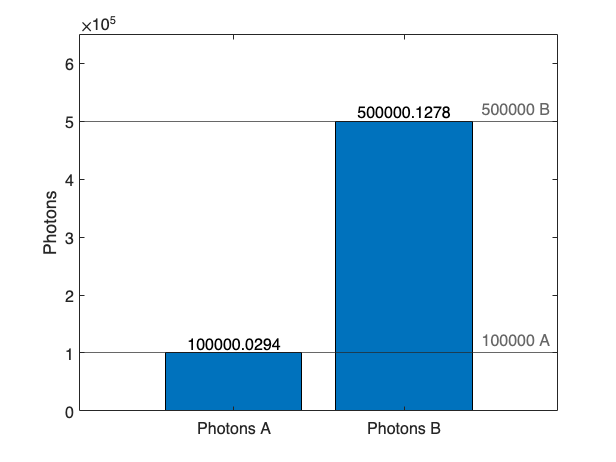

text(bar_x,[Photons_A Photons_B],labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
ylabel('Photons')
ylim([0 650000])
yline([100000 500000], '-', {'100000 A', '500000 B'})

title(['100000 A ', num2str(tau1), 'ns + 500000 B ', num2str(tau2), 'ns + ', num2str(autofluo_number), ' ', num2str(tau_adding), 'ns'])

Unrecognized function or variable 'tau_adding'.

% what if I fix the pop1 and pop2 at value that I think are more reasonable

% for tau2 = 2.5 ns, with analytical sensor histograms only, pop1 = 9304,
% pop2 = 37576, chi2 = 1.7*10^-5, photons1 = 100000, photons2 = 500000 pop2
% = 16014

% for tau2 = 6 ns, with analytical sensor histograms only, pop1 = 11529,
% pop2 = 15683, chi2 = 1.2017, photons1 = 12392, photons2 = 48966

% after adding autofluorescence, pop1 = 14773, pop2 = 34211, chi2 = 3.8260,
% photons1 = 15878, photons2 = 45522

% if I make pop1 = 10000, pop2 = 35000
% pop1 = 10000;
% pop2 = 35000;

chan = 1;

pop1_plot = [14700 9300 12000];
pop2_plot = [34200 37600 35900];

% pop1_plot = [11500 9300 10400];
% pop2_plot = [15700 16000 15800];

pop1_start = 9000;
pop1_end = 16000;

pop2_start = 33000;
pop2_end = 38000;

% pop2_start = 15000;
% pop2_end = 16500;

pop1_all = pop1_start:100:pop1_end;
pop2_all = pop2_start:100:pop2_end;

pop1_index = zeros(1, length(pop1_plot))

pop1_index =      0     0     0


pop2_index = zeros(1, length(pop2_plot))

pop2_index =      0     0     0



for i = 1:length(pop1_plot)
    pop1_index(i) = find(pop1_all == pop1_plot(i));
end

for i = 1:length(pop2_plot)
    pop2_index(i) = find(pop2_all == pop2_plot(i));
end


redchisq = zeros(length(pop1_all), length(pop2_all));

for i = 1:length(pop1_all)

    pop1 = pop1_all(i);

    for j = 1:length(pop2_all)

        pop2 = pop2_all(j);

        histogram_A = Exp1Hist(xsim, tau1, pop1, prf);
        histogram_B = Exp1Hist(xsim, tau2, pop2, prf);
        
        histogram_total = histogram_A + histogram_B;
        residual = histogram_analytical - histogram_total;
        chisq = sum(residual(:).*residual(:) ./ max(histogram_total(:),1));
        redchisq(i, j) = chisq/(length(histogram_analytical)-spc.fits{chan}.nFreeParams);

    end


end

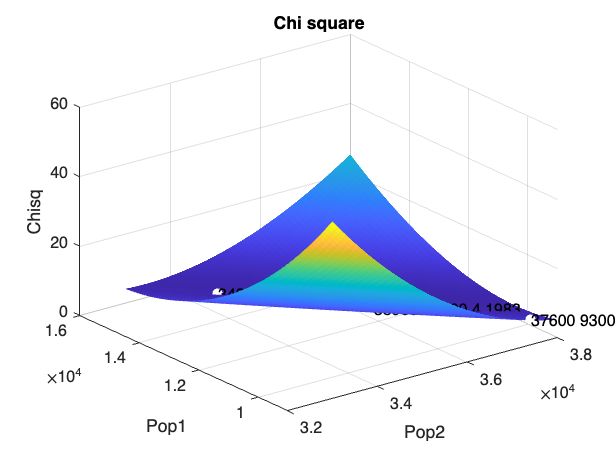


plot_text = {};
plot_point = zeros(1, length(pop1_plot));

for i = 1:length(pop1_plot)
    plot_point(i) = redchisq(pop1_index(i), pop2_index(i));
    plot_text{i} = [num2str(pop2_plot(i)), ' ',num2str(pop1_plot(i)), ' ', num2str(redchisq(pop1_index(i), pop2_index(i)))];
end

figure
s = surf(pop2_all, pop1_all, redchisq);
hold on
scatter3(pop2_plot, pop1_plot, plot_point, 40, 'filled', 'w')
text(pop2_plot, pop1_plot, plot_point, string(plot_text))
xlabel('Pop2')
ylabel('Pop1')
zlabel('Chisq')
title('Chi square')
s.EdgeColor = 'none';

% Plot the iterations
iteration_1 = zeros(1, length(beta_iterations));
iteration_2 = zeros(1, length(beta_iterations));
sses = zeros(1, length(beta_iterations));
step = 1:1:length(beta_iterations)

step =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


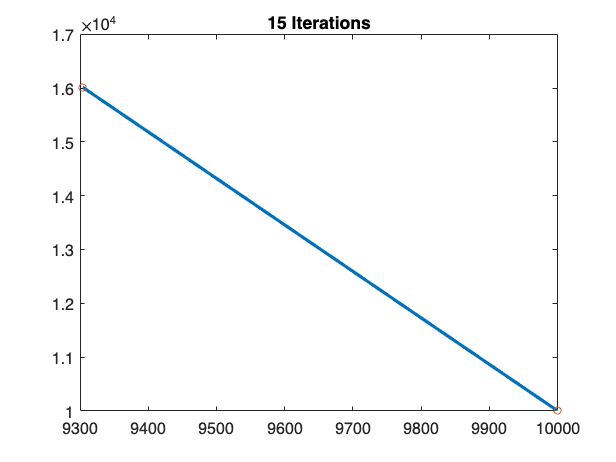


for i = 1:length(beta_iterations)
    iteration_1(i) = beta_iterations{i}(1);
    iteration_2(i) = beta_iterations{i}(2);

    sses(i) = sse_iterations{i};
end

figure
plot(iteration_1, iteration_2, 'LineWidth', 2)
hold on
scatter(iteration_1, iteration_2, 20, 'o')
title([num2str(length(beta_iterations)), ' Iterations'])

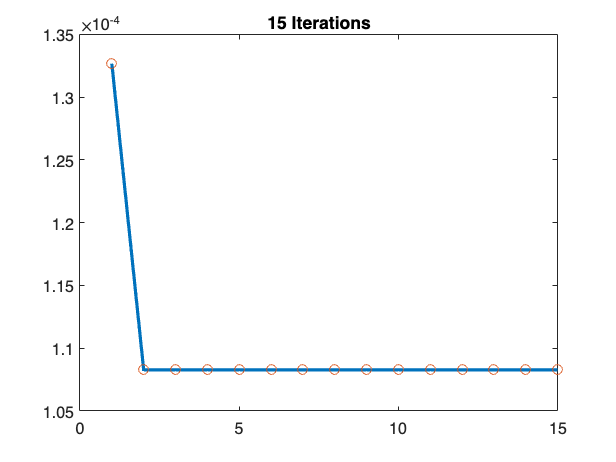


figure
plot(sses, 'LineWidth', 2)
hold on
scatter(1:1:length(sse_iterations), sses)
title([num2str(length(beta_iterations)), ' Iterations'])

% Generation of population B, corresponding to different lifetime tau2
for i = 1:length(tau2_all)
    tau2 = tau2_all(i);
    PopulationName=['Simulation_population_B_',num2str(tau2), 'ns.mat']; % Define single exponential population name
    GenPop512_exp1_v2(1000000, tau2, 50, PopulationName);  % Generate the single exponential population
end

% the script for batch processing of simulation of sample A
% Simulation_sampleA.m
rng('shuffle','twister') % Shuffle the random number generator
n_sensor_all = zeros(500, 256); % For each sensor sample size condition, simulated data will be saved as row vectors in 'n_all' varible 
for k=1:500 % Simulating 500 times
    [n1, n2, n] = FLIMsim512_v3(50, SS,PrfName, PopulationName); % Simulation with corresponding sample size (SS), IRF (PrfName), and population (PopulationName)
    n_sensor_all(k, :) = n; % Save simulated data into n_all
end
% Save the simulated data under each p1 condition as one file
simulated_name = ['Simulated_data/SampleA', num2str(SS), '_sensor.mat'];
save(simulated_name, 'n_sensor_all')

% the script for batch processing of simulation of sample B
% Simulation_sampleB.m
rng('shuffle','twister') % Shuffle the random number generator
n_sensor_all = zeros(500, 256); % For each sensor sample size condition, simulated data will be saved as row vectors in 'n_all' varible 
for k=1:500 % Simulating 500 times
    [n1, n2, n] = FLIMsim512_v3(50, SS,PrfName, PopulationName); % Simulation with corresponding sample size (SS), IRF (PrfName), and population (PopulationName)
    n_sensor_all(k, :) = n; % Save simulated data into n_all
end
% Save the simulated data under each p1 condition as one file
simulated_name = ['Simulated_data/SampleB', num2str(SS), '_sensor.mat'];
save(simulated_name, 'n_sensor_all')

c = parcluster()

% create the scripts for batch processing
edit Simulation_sampleA
% edit Simulation_sampleB

% batch processing for simulation of sample A with different photon numbers

PopulationName='Simulation_population_A_2ns.mat'; % Define the single exponential population name of sample A

for j=1:length(SS_samples_A)
    
    SS=SS_samples_A(j); % Define the sensor A sample size
%     Simulation_sampleA
    batch('Simulation_sampleA', 'Pool',4) % Parallel running simulation of each A sample size
    
end


% batch processing for simulation of sample B with different lifetime
for i_B = 1:length(SS_samples_B)

    % different B counts
    SS = SS_samples_B(i_B);
    
    for i = 1:length(tau2_all)
        
        tau2 = tau2_all(i); % define the B lifetime
        PopulationName=['Simulation_population_B_',num2str(tau2), 'ns.mat']; % Define single exponential population name
        batch('Simulation_sampleB')  % parallel running simulation of each B sample size and B lifetime
    
    end

end

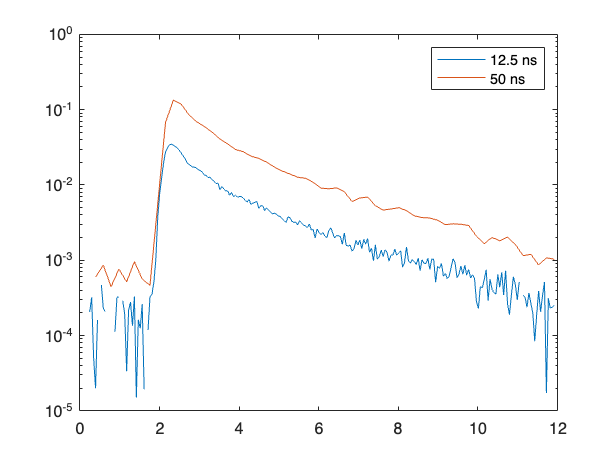

% Create the probability distribution function of autofluorescence
% corresponding to a 50 ns cycle

autofluo_corrected(246:end) = 0;
autofluo_corrected = autofluo_corrected/sum(autofluo_corrected);

x_axis = 1:1:256;
autofluo_50ns = zeros(1,256);

for i = 1:64
    autofluo_50ns(i) = sum(autofluo_corrected((i-1)*4+1:(i-1)*4+4));

end

figure
semilogy(x_axis*(12.5/256), autofluo_corrected)
hold on
semilogy(x_axis*(50/256), autofluo_50ns)
legend('12.5 ns', '50 ns')


autofluo_number = AF_mean_corrected*3.2;

% This is to create the distribution of background
bkgrd_AP_distribution = zeros(1, 256) + 1/251; % Creating the probability density distribution: background evenly distributed over time; the experimental histogram channel 1-4 and 256 are 0; thus there are 251 channels that add up to 1
bkgrd_AP_distribution([1,2,3,4,256]) = 0; % Probability density distribution for background: channel 1-4 and 256 as 0
bkgrd_sum = round(autofluo_bkgrd*251)*3.2; % background total number: autofluo_bkgrd is background photon number per channel from the fitting of autofluorescence

% Check the batch processing script for simulationg autofluorescence and
% afterpulse/background

edit Autofluo_corrected_simulation_20231201
% edit Bkgrd_AP_simulation_20231201.m

% Batch processing of simulation of corrected autofluorescence
for i_B = 1:length(SS_samples_B) % For each sample B photon count condition:

    SS_samples = SS_samples_A + SS_samples_B(i_B); % Corresponding to each sample B photon counts, create the vector for total photon numbers of A and B

    for j=1:length(SS_samples)
        SS = SS_samples(j);
        batch('Autofluo_corrected_simulation_20231201', 'Pool', 4)
        batch('Bkgrd_AP_simulation_20231201', 'Pool', 4)
    end

end

## Running ftting of the simulated combined data: A and B samples, autofluorescence, afterpulse/background

global FixBackground FixedBackground

FixBackground = 0;
FixedBackground = 0;

ch = 1; % only for FLIM channel 1
load(PrfName)
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (50/256)*1000;
spc.datainfo.pulseInt = 50;
spc.fits{1}.fitstart = 1*spc.datainfo.psPerUnit/1000;
spc.fits{1}.fitend = 50;

channel_width = 50/256;
pulse_width = 50;
range = [1 256];

chan = 1;

sample_num = 500;

% Conditions to run the analysis: different sample B size; different
% starting A for intensity change to start with
cd('/Volumes/ChenLabHDDB/Simulation/Simulation_Multiplexing_50ns_20240503')

SS_samples_B_all = [100000 500000 1000000];
Starting_As = 200000:100000:800000;
tau2_all=[2.5 3 3.5 4 6]; % tau2 

% SS_samples_B_all = 500000;
% Starting_As = 100000;
% tau2_all=[2.5 6]; % tau2 
% sample_num = 500;


% running fitting with simulated A and B samples together, and with
% autofluorescence, background signal and after pulse.

xsim = (0:1:511)*(50/256); % x axis lifetime steps for generating the histogram for sample A or B

ch = 1; % only for FLIM channel 1

spc.fits{1}.beta2 = tau1; % fix the tau1


for i_BCounts = 1:length(SS_samples_B_all) % Cycling through different sample B sizes

    SS_samples_B = SS_samples_B_all(i_BCounts); % Define the sample B size

    for i_tau2 = 1:length(tau2_all) % Cycling through different B lifetimes
    
        n_sensor_all_B = []; % initialize the simulated B histograms matrix
        tau2 = tau2_all(i_tau2);
        spc.fits{1}.beta4 = tau2; % Define the B lifetime and fix it for fitting
        
        load(['Simulated_data/SampleB_', num2str(tau2), '_', num2str(SS_samples_B), '_sensor.mat'])
        n_sensor_all_B = n_sensor_all; % Load the simulated B with corresponding B sample size and lifetimes
    
        for i_StartingA = 1:length(Starting_As) % Different starting sample A

            % Create variable to save fitted p1, fitting parameters, and
            % individual histograms corresponding to derived A and B from fitting
            p1_fitted_all = {}; 
            fitting_parameters_all = {}; 
            histogram_mixed_all = {}; 
            histogram_A_fitted_all = {};
            histogram_B_fitted_all = {};
            
            % Create variable to save photon number of A and B from fitting
            Photons_A_all = {};
            Photons_B_all = {};
            
            % Create variable to save histograms for plotting (mean and std)
            histogram_mixed_plot_all = {};
            histogram_A_fitted_plot_all = {};
            histogram_B_fitted_plot_all = {};
        
            histogram_mixed_plot_all2 = [];
            histogram_A_fitted_plot_all2 = [];
            histogram_B_fitted_plot_all2 = [];

            Starting_A = Starting_As(i_StartingA); % Define starting A photon number
            SS_samples_A = Starting_A:5000:(Starting_A*1.5); % With this starting A, what are the simulated sample sizes

            SS_samples = SS_samples_B + SS_samples_A; % With this sample B size and sample A seris, calculate the total photon number series
        
            n_all = {}; % create the cell that contains the data (500 histograms) to run the fitting using defined fitting function
            
            
            for i = 1:length(SS_samples_A) % for each sample A size from the seris
                
                SS_A = SS_samples_A(i); % Define A size
                SS = SS_samples(i); % Define total number size

                % load simulated sample A, autofluorescence, and
                % background/aferpulse
                n_sensor_all = [];
                n_auto_all = [];
                n_bkgrd_all = [];

                load(['Simulated_data/SampleA_', num2str(SS_A), '_sensor.mat'])
                load(['Simulated_data_0617/autoF_', num2str(SS), '.mat'])
                load(['Simulated_data_0617/bkgrd_AP_', num2str(SS), '.mat'])

                % Add them up together for running fitting
                n_all{1} = n_sensor_all_B + n_sensor_all + n_auto_all + n_bkgrd_all;
            
                % Calculate the average trace of the mixed histogram
                histogram_mixed_all{i} = n_all{1};
                histogram_mixed_plot_all{i} = [transpose(mean(n_all{1})), transpose(std(n_all{1}))]; % Generate a 256x2 matrix; 1st column is the average photon number to each of the 256 channel; 2nd colunm is the standard deviation
            
                % Running fitting of the mixed histogram and save the
                % fitted p1 and other fitting parameters
%                 [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all, chan, range, channel_width, prf, pulse_width);
                [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all);
                p1_fitted_all{i} = p1_fitted;
                fitting_parameters_all{i} = fitting_parameters;

%                 figure('Visible', 'off')
%                 semilogy((5:1:256)*(50/256), spc.lifetimes{1}(5:1:256), 'LineWidth', 3)
%                 hold on
%                 semilogy((5:1:256)*(50/256), spc.fits{1}.curve, 'LineWidth', 2)
%                 xlabel('Lifetime(ns)')
%                 ylabel('Photons')
%                 legend('Simulated data', 'Fitted curve')
%                 hold off
%                 FigureName = ['Figures/BPhotons_', num2str(SS_samples_B), '_tau2_', num2str(tau2), 'ns_APhotons', num2str(SS_A), '.png'];
%                 saveas(gcf, FigureName)

            
                % Generate the histogram of A and B based on fitted pop1 and
                % pop2 values

                histogram_A_fitted = zeros(500, 256); % Initialize histogram variable
                histogram_B_fitted = zeros(500, 256);
            
                Photons_A = zeros(500, 1); % Initialize photon count (intensity) variable
                Photons_B = zeros(500, 1);
            
                for k = 1:500

                    % using customized function Exp1Hist to generate the
                    % histogram and calculate the photon number based on fited p1 and p2
                    histogram_A_fitted(k,:) = Exp1Hist(xsim, tau1, fitting_parameters{6}(k), prf);
                    histogram_B_fitted(k,:) = Exp1Hist(xsim, tau2, fitting_parameters{7}(k), prf);
            
                    % Use the sum of the histogram as the photon number (intensity)
                    Photons_A(k) = sum(histogram_A_fitted(k,:));
                    Photons_B(k) = sum(histogram_B_fitted(k,:));
                end
            
                % saving the calculated histograms
                histogram_A_fitted_all{i} = histogram_A_fitted;
                histogram_B_fitted_all{i} = histogram_B_fitted;
            
                Photons_A_all{i} = Photons_A;
                Photons_B_all{i} = Photons_B;
            
                histogram_A_fitted_plot_all{i} = [transpose(mean(histogram_A_fitted)), transpose(std(histogram_A_fitted))];
                histogram_B_fitted_plot_all{i} = [transpose(mean(histogram_B_fitted)), transpose(std(histogram_B_fitted))];
        
                histogram_mixed_plot_all2 = [histogram_mixed_plot_all2 histogram_mixed_plot_all{i}];
                histogram_A_fitted_plot_all2 = [histogram_A_fitted_plot_all2 histogram_A_fitted_plot_all{i}];
                histogram_B_fitted_plot_all2 = [histogram_B_fitted_plot_all2 histogram_B_fitted_plot_all{i}];
            
            end
        
            save(['Fitting_results_B',num2str(tau2),'ns', num2str(SS_samples_B),'_StartingA', num2str(Starting_A), '_20240624', '.mat'], 'p1_fitted_all', 'fitting_parameters_all',...
                'histogram_mixed_all', 'histogram_A_fitted_all', 'histogram_B_fitted_all',...
                'Photons_A_all', 'Photons_B_all',...
                'histogram_mixed_plot_all', 'histogram_A_fitted_plot_all', 'histogram_B_fitted_plot_all', ...
                'histogram_mixed_plot_all2', 'histogram_A_fitted_plot_all2', 'histogram_B_fitted_plot_all2')
        end
    
    end

end

p1_fitted =     0.8246
    0.8210
    0.8232
    0.8183
    0.8320
    0.8290
    0.8093
    0.8230
    0.8200
    0.8165


tau_empTrunc =     5.0312
    5.0432
    5.0592
    5.0214
    5.0676
    5.0381
    5.0373
    5.0387
    5.0633
    5.0486


fitting_parameters = 1×7 cell array
    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}


p1_fitted =     0.8521
    0.8074
    0.7948
    0.8262
    0.8218
    0.8329
    0.8247
    0.8232
    0.8268
    0.8174


tau_empTrunc =     5.0082
    5.0181
    5.0229
    5.0090
    5.0282
    5.0191
    5.0597
    5.0524
    5.0302
    5.0449


fitting_parameters = 1×7 cell array
    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}


p1_fitted =     0.8453
    0.8478
    0.8388
    0.8283
    0.8310
    0.8227
    0.8175
    0.8408
    0.8357
    0.8230


tau_empTrunc =     5.0029
    5.0021
    5.0073
    5.0391
    5.0138
    5.0513
    5.0258
    5.0146
    5.0041
    5.0202


fitting_parameters = 1×7 cell array
    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}


p1_fitted =     0.8438
    0.8445
    0.8204
    0.8191
    0.8405
    0.8568
    0.8335
    0.8218
    0.8467
    0.8286


tau_empTrunc =     5.0011
    4.9936
    5.0267
    4.9970
    5.0303
    5.0088
    5.0013
    4.9977
    4.9941
    5.0315


fitting_parameters = 1×7 cell array
    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}    {500×1 double}


% calculate the power of detecting intensity change in A, using the
% equation: beta = 1 - normcdf(1.96-change/SEM)

cd('/Volumes/ChenLabHDDB/Simulation/Simulation_Multiplexing_50ns_20240503')

SS_samples_B_all = [100000 500000 1000000]; % all the sample B conditions
Starting_As = 200000:100000:800000; % different starting sample A conditions

% Create variables for saving the minimum detectable differences of
% intensity change
% MDD_dIntensity_all = {}; % relative change
% MDD_abs_dIntensity_all = {}; % absolute change
Beta_allConditions = {}; % confidence levels


for i_BCounts = 1:length(SS_samples_B_all) % For each sample conditions

    SS_samples_B = SS_samples_B_all(i_BCounts); % Define sample B value

%     MDD_dIntensity = zeros(length(Starting_As), 5); % initialize minimum detectable difference variable for certain B number condition
%     MDD_abs_dIntensity = zeros(length(Starting_As), 5);

    for i_StartingA = 1:length(Starting_As)  % For each starting A conditions

        Starting_A = Starting_As(i_StartingA);
        SS_samples_A = Starting_A:5000:(Starting_A*1.5); % Define starting A value and the corresponding sample A counts with range of 1-1.5 fold change
    
        SS_samples = SS_samples_B + SS_samples_A;
%         d_intensity = (5000:5000:Starting_A*0.5)/Starting_A; % calculated the relative intensity change series
%         abs_d_intensity = 5000:5000:Starting_A*0.5; % calculated the absolute intensity change series

        Beta_all = []; % A matrix of statistical powers; each row is for a specific change of A; each column is for a tau2 condition
    
        for i_tau2 = 1:length(tau2_all) % For each sample B tau conditions

            tau2 = tau2_all(i_tau2); % Define the tau2 value for sensor B

            % Initialize the variable for standard deviation, mean, and
            % power of the sample A photons
            A_std = zeros(1, length(SS_samples_A));
            A_mean = zeros(1, length(SS_samples_A));
            Betas = zeros(length(SS_samples_A)-1, 1);

            % Load the fitting results corresponding to this tau2, sample
            % B, and starting A condition
            load(['Fitting_results_B',num2str(tau2),'ns', num2str(SS_samples_B),'_StartingA', num2str(Starting_A), '_20240624', '.mat'])
            
            for i = 1:length(SS_samples_A)
                A_std(i) = std(Photons_A_all{i}); % calculate the standard deviation of photons from A
                A_mean(i) = mean(Photons_A_all{i}); % calculate the mean of A photon counts
        
            end

            for i = 1:length(SS_samples_A)-1 % for multiple steps from changed A

                dA_intensity = A_mean(i+1) - A_mean(1); % calculate the mean A change
                SEM = sqrt(A_std(1)^2 + A_std(i+1)^2); % calculate the SEM of the A change
        
                Betas(i) = 1 - normcdf(1.96 - (dA_intensity/SEM)); % calculate the confidence level based mean and std of A change
        
            end
        
            Beta_all = [Beta_all Betas]; % collect the confidence levels calculated
            
        end

        % Transform where the power value start to be bigger than 0.8 to
        % the minimum detectable difference 
        Beta_allConditions{i_BCounts}{i_StartingA} = Beta_all; % save the power values
%         Beta_all_08 = sum(Beta_all < 0.8); % Using 0.8 as a threshold of confidence level, find the step where confidence level starts to be bigger than 0.8
%         MDD_dIntensity(i_StartingA, :) = d_intensity(Beta_all_08); % By summing the results of Beta_all < 0.8 we got the row numbers where power is about to be bigger than 0.8
%         MDD_abs_dIntensity(i_StartingA, :) = abs_d_intensity(Beta_all_08);

    end

    % Save the calculated variables from different conditions 
%     MDD_dIntensity_all{i_BCounts} = MDD_dIntensity;
%     MDD_abs_dIntensity_all{i_BCounts} = MDD_abs_dIntensity;

end

%% This section is to calcuate the minimum detectble difference of intensity change (giving a power of bigger than 0.8)

% Initialize the cell structure to save the 5-parameter logistic curve fitting results, interpolated values, and minimum
% detectable difference based on the interpolation
MDD_all = {};
beta_interpolated_all = {};
L5P_fitting_cf = {};
L5P_fitting_G = {};
mkdir('Figures') % create a folder to save all the figures generated


for i_BCounts = 1:length(SS_samples_B_all) % For each sample conditions
    SS_samples_B = SS_samples_B_all(i_BCounts); % Define sample B value

    MDD = zeros(length(tau2_all), length(Starting_As));
    for i_StartingA = 1:length(Starting_As) % For each starting A conditions

        % Define the starting A and A photon count change conditions with a
        % maximum of 50% change
        Starting_A = Starting_As(i_StartingA); 
        x_dintensity = transpose((5000:5000:Starting_A*0.5)/Starting_A)*100; % Percentage of intensity change of A

        beta_interpolated = zeros(50, length(tau2_all)); % Initialize the interpolated power, corresponding to 1:1:50% of intensity change

        for i_tau2 = 1:length(tau2_all)  % For each sample B tau conditions

            tau2 = tau2_all(i_tau2); % Define tau2 for sample B lifetime

            y_beta = Beta_allConditions{i_BCounts}{i_StartingA}(:,i_tau2); % Pull the statistical power calculated

            [cf, G] = L5P(x_dintensity, y_beta); % Fit a 5-parameter logistic curve; cf is the fitting results; G is the evaluation of the fitting
            L5P_fitting_G{i_BCounts}{i_StartingA, i_tau2} = G;
            L5P_fitting_cf{i_BCounts}{i_StartingA, i_tau2} = cf;
     
            % Load the fitted curve variables
            A = cf.A;
            B = cf.B;
            C = cf.C;
            D = cf.D;
            E = cf.E; 

            % x axis to be interpolated
            x_interpolation = transpose(1:1:50);

            % Interpolated Y based on the 5-parameter logistic curve
            % function; F(x) = D+(A-D)/((1+(x/C)^B)^E)
            beta_interpolated(:,i_tau2) = D + (A-D)./((1+(x_interpolation./C).^B).^E);

            % Based on the curve, calculate the intensity change
            % corresponding to 0.8 confidence level
            syms x
            eqn = D + (A-D)/((1+(x/C)^B)^E) == 0.8;
            S = solve(eqn, x, 'Real', true);

            % Save the 0.8 confidence level intensity change as minimal
            % detectable difference at this condition
            if isempty(S)

                MDD(i_tau2, i_StartingA) = min(x_dintensity);
            else

                MDD(i_tau2, i_StartingA) = double(S);

            end

            % Plot and save the raw data points (power vs intensity
            % change), fitted curve, and threshold that gave a 80% power
            figure('Visible','off')
            plot(x_dintensity, y_beta, 'LineWidth',3, 'Color','b')
            hold on
            scatter(x_dintensity, y_beta, 40, 'filled', 'b')
            hold on
            plot(x_interpolation, beta_interpolated(:,i_tau2), 'LineWidth',2, 'Color','r')
            hold on
            yline([0.8], '--')
            if isempty(S) == 0

                xline([double(S)],'-',{num2str(double(S))}, 'LineWidth',2, 'Color','k')
            end
            legend(' ', 'Simulated data', 'Fitted curve', '0.8', 'MDD')
            xlabel('Intensity change (%)')
            ylabel('Confidence level')
            figure_name = ['Sensor B ',num2str(SS_samples_B), ', starting A ', num2str(Starting_A), ', lifetime difference ', num2str(tau2 - 2), ' ns'];
            title(figure_name)
            saveas(gcf, ['Figures/', figure_name, '.png'])
            hold off
            

        end

        % Save the interpolated values calculated
        beta_interpolated_all{i_BCounts}{i_StartingA} = beta_interpolated;


        
    end

    % Save the minimum detectable difference values calculated based on
    % interpolation
    MDD_all{i_BCounts} = MDD;

end


Actual_APhotons = 4:5000/100000:6;

APhotons_dLifetime05ns = zeros(length(Actual_APhotons),2);
APhotons_dLifetime4ns = zeros(length(Actual_APhotons),2);

BPhotons_dLifetime05ns = zeros(length(Actual_APhotons),2);
BPhotons_dLifetime4ns = zeros(length(Actual_APhotons),2);

% load('/Volumes/ChenLabHDDB/Simulation/Simulation_Multiplexing_50ns_20240503/Fitting_results_B2.5ns500000_StartingA200000_20240610.mat')
load('Fitting_results_B2.5ns500000_StartingA400000_20240624.mat')
for i = 1:length(Actual_APhotons)
    APhotons_dLifetime05ns(i,1) = mean(Photons_A_all{i})/100000;
    APhotons_dLifetime05ns(i,2) = std(Photons_A_all{i})/100000;

    BPhotons_dLifetime05ns(i,1) = mean(Photons_B_all{i})/100000;
    BPhotons_dLifetime05ns(i,2) = std(Photons_B_all{i})/100000;

end

% load('/Volumes/ChenLabHDDB/Simulation/Simulation_Multiplexing_50ns_20240503/Fitting_results_B6ns500000_StartingA200000_20240610.mat')
load('Fitting_results_B6ns500000_StartingA400000_20240624.mat')
for i = 1:length(Actual_APhotons)
    APhotons_dLifetime4ns(i,1) = mean(Photons_A_all{i})/100000;
    APhotons_dLifetime4ns(i,2) = std(Photons_A_all{i})/100000;

    BPhotons_dLifetime4ns(i,1) = mean(Photons_B_all{i})/100000;
    BPhotons_dLifetime4ns(i,2) = std(Photons_B_all{i})/100000;

end



% calculate the t test results with intensity of sample B (which is supposed to be constant)

SS_samples_B_all = [100000 500000 1000000]; % all the sample B conditions
Starting_As = 200000:100000:800000; % different starting sample A conditions

% Create cell structure for saving the significant values tested from t test
TestSignificance_allConditions = {};
TestSignificance_check_allConditions = {};


for i_BCounts = 1:length(SS_samples_B_all) % Cycling through all each sample B conditions

    SS_samples_B = SS_samples_B_all(i_BCounts); % Define sample B value

    TestSignificance_check_all = zeros(length(Starting_As), length(tau2_all)); % initialize the matrix for the t test results

    for i_StartingA = 1:length(Starting_As) % For each starting A conditions

        Starting_A = Starting_As(i_StartingA);
        SS_samples_A = Starting_A:5000:(Starting_A*1.5); % Define starting A value and the corresponding sample A counts with range of 1-1.5 fold change
    
%         SS_samples = SS_samples_B + SS_samples_A; % Photon count seris with A and B together

        TestSignificance_all = []; 
    
        for i_tau2 = 1:length(tau2_all)
    
            % Calculate mean and standard deviation of sample B photon
            % counts from fitting from loaded fitting results
            B_std = zeros(1, length(SS_samples_A));
            B_mean = zeros(1, length(SS_samples_A));
            TestSignificance = zeros(length(SS_samples_A)-1, 1);

            % Load the fitting results corresponding to this tau2, sample
            % B, and starting A condition
            load(['Fitting_results_B',num2str(tau2),'ns', num2str(SS_samples_B),'_StartingA', num2str(Starting_A), '_20240603', '.mat'])
            
            for i = 1:length(SS_samples_A)
                B_std(i) = std(Photons_B_all{i}); % calculate B mean
                B_mean(i) = mean(Photons_B_all{i}); % calcuated B std
            end

            for i = 1:length(SS_samples_A)-1 % For each step of intensity change

                dB_intensity = abs(B_mean(i+1) - B_mean(1)); % Calculate mean change
                SEM = sqrt(B_std(1)^2 + B_std(i+1)^2); % Calculate SEM of the intensity change
        
                % Testing for significance based on change/SEM; if > 1.96,
                % then significant for t test (1); if not, not significant for
                % t test (0)
                if dB_intensity/SEM >= 1.96
                    TestSignificance(i) = 1;
                else
                    TestSignificance(i) = 0;
                end
        
            end
        
            % Saving t test results for each conditions
            TestSignificance_all = [TestSignificance_all TestSignificance];
            
        end

        % Saving t test results for each conditions
        TestSignificance_allConditions{i_BCounts}{i_StartingA} = TestSignificance_all;

        TestSignificance_check = sum(TestSignificance_all); % Sum up to check whether all of them are 0
        TestSignificance_check_all(i_StartingA, :) = TestSignificance_check;

    end

    % Saving t test results for each conditions
    TestSignificance_check_allConditions{i_BCounts} = TestSignificance_check_all;

end

save('analysis.mat')

% function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all, chan,range, channel_width, prf, pulse_width)

function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all)

global spc
ch = 1;

pop1 = zeros(sample_num, 1);  % population 1
pop2 = zeros(sample_num, 1);  % population 2
p1_fitted = zeros(sample_num, 1);  % fitted p1
tau_avg = zeros(sample_num, 1); % lifetime calculated based on the fitting curve calculated to infinite
tau_avgTrunc = zeros(sample_num, 1); % lifetime calculated based on the fitting curve within fitting range
tau_empTrunc = zeros(sample_num, 1); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
chi2 = zeros(sample_num, 1); % chi square from fitting
beta6 = zeros(sample_num, 1); % SHG term from fitting
backcorr = zeros(sample_num, 1); % background term from fitting

fitting_parameters = {};

for k = 1:sample_num

    spc.lifetimes{1} = n_all{1}(k,:);

    if length(n_all) > 1

        for i_components = 2:length(n_all)

            spc.lifetimes{1} = spc.lifetimes{1} + n_all{i_components}(k,:);
        end

    end


    % initiate the fitting parameters
            
    spc.fits{1}.beta1 = 1000; % p1 and p2 as 0.5
    spc.fits{1}.beta3 = 1000;
    spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
    spc.fits{1}.beta6 = 0;

%     lifetime = spc.lifetimes{1};

    % Running the fitting
    spc_fitexp2prfGY(ch); 
%     spc_fitexp2prfPM(chan, range, lifetime, channel_width, prf, pulse_width);

    pop1(k,1) = spc.fits{ch}.beta1;
    pop2(k,1) = spc.fits{ch}.beta3;
    p1_fitted(k,1)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
    tau_avg(k,1)=spc.fits{ch}.avgTau; 
    tau_avgTrunc(k,1)=spc.fits{ch}.avgTauTrunc;
    tau_empTrunc(k,1)=spc.fits{ch}.EmpTauTrunc;
    chi2(k,1)=spc.fits{ch}.redchisq;
    beta6(k,1)=spc.fits{ch}.beta6;
    backcorr(k,1)=spc.fits{ch}.backCorr;

end

fitting_parameters{1} = tau_avg;
fitting_parameters{2} = tau_avgTrunc;
fitting_parameters{3} = chi2;
fitting_parameters{4} = beta6;
fitting_parameters{5} = backcorr;
fitting_parameters{6} = pop1;
fitting_parameters{7} = pop2;

end


function y = Exp1Hist(xsim, tau, TP, prf)

ysim = TP*exp(-xsim/tau);

ysim_conv = conv(ysim, prf);
y = ysim_conv(1:256) + ysim_conv(257:512);

end

function EmpLft = CalcEmpLft(range, n, Laser_cycle)

x_axis = (1:1:(range(2)-range(1)+1))*(Laser_cycle/256);
EmpLft = sum(n(range(1):range(2)).*x_axis)/sum(n(range(1):range(2)));

end